# #Crank-Slider Mechanism Kinetics

# Task 2

## **KINEMATICS**

%Task X
clear
clc
close all

%FIRST COMPUTE KINEMATICS FOR THE SYSTEM
L1 = .20; % [cm]
L2 = .60; % [cm]
Y = .30; % [cm]

dt = 0.001;
t = 0:dt:10;

theta1(1) = 60/180 * pi; % [rad]
w1(1) = 0; % [rad/s]
alpha1(1) = 0; % [rad/s^2]

[theta2(1), w2(1), X(1), vc(1)] = ComputeKinematics(theta1(1), w1(1), L1, L2, Y)

theta2 = 0.2129

w2 = 0

X = 0.6864

vc = 0


for i=1:length(t)
    alpha1(i+1) = 0;
    w1(i+1) = 0.2*pi;
    theta1(i+1) = 0.2*pi*t(i);
[theta2(i+1), w2(i+1), X(i+1), vc(i+1)] = ComputeKinematics(theta1(i+1), w1(i+1), L1, L2, Y);
end

## **KINETICS**

Crank-slider mechanism kinetics and solving N linear equations with N unknowns

clear
clc

L1 = .20; % [cm] Length of link AB
L2 = .60; % [cm] Length of link BC
Y = .30; % [cm] Horizontal offset of slider

m1 = 0.25; % mass of link AB
m2 = 0.75; % mass of link BC
mc = 0.5; % mass of the slider

IA = (1/3)*m1*L1^2; % moment of inertia of link AB about A
IG2 = (1/12)*m2*L2^2; % moment of inertia of link BC about its center of gravity G2
tau = 0.2; % [N-m] input torque
g = 9.81; % [m/s^2] gravitational constant

theta1 = 60/180 * pi; % [rad] angle theta1
w1 = 0; % [rad/s] angular velocity of link AB

%%%%%

%From the equations you developed last lab, find theta2 and w2.
theta2 = asin((Y-L1*sin(theta1))/(L2));
w2 = (L1*cos(theta1)*w1)/(-L2*cos(theta2));

%%%%%

%Now, define your system of equations using kinetics (Newton-Euler) and
%kinematics (relative acceleration).
%You should have X equation and X unknowns. For me, my system is made of 14 equations and 14 unknowns

%When you have your equations, sort them into matrix A (coefficients
%matrix) and constants vector (Right hand side of the your equations made only of known quantities)

%For me, b is 14x1 and A is 14x14

%SUGGESTION: write down even row from matrix A individually and make sure
%the number of columns of these rows remain the same:

b = [0;                                                 % Result 1
    m1*g;                                               % Result 2
    -m1*g*(L1/2)*cos(theta1) + tau;                     % Result 3
    -(w1^2)*(L1/2)*cos(theta1);                         % Result 4
    -(w1^2)*(L1/2)*sin(theta1);                         % Result 5
    0;                                                  % Result 6
    -m2*g;                                              % Result 7
    0;                                                  % Result 8
    -(w1^2)*L1*cos(theta1) - (w2^2)*(L2/2)*cos(theta2); % Result 9
    -(w1^2)*L1*sin(theta1) - (w2^2)*(L2/2)*sin(theta2); % Result 10
    0;                                                  % Result 11
    mc*g;                                               % Result 12
    -(w1^2)*L1*cos(theta1) - (w2^2)*L2*cos(theta2);     % Result 13
    (w1^2)*L1*sin(theta1) + (w2^2)*L2*sin(theta2)];     % Result 14

%                      1,                   2,   3,   4,  5,  6,  7, 8, 9,                 10,                  11,                 12,                  13,14
A = [                  0,                   0, -m1,   0,  0,  0,  0, 1, 0,                  1,                   0,                  0,                   0, 0;  % Equation 1
                       0,                   0,   0, -m1,  0,  0,  0, 0, 1,                  0,                   1,                  0,                   0, 0;  % Equation 2
                      IA,                   0,   0,   0,  0,  0,  0, 0, 0,     L1*sin(theta1),     -L1*cos(theta1),                  0,                   0, 0;  % Equation 3
      (L1/2)*sin(theta1),                   0,   1,   0,  0,  0,  0, 0, 0,                  0,                   0,                  0,                   0, 0;  % Equation 4
     -(L1/2)*cos(theta1),                   0,   0,   1,  0,  0,  0, 0, 0,                  0,                   0,                  0,                   0, 0;  % Equation 5
                       0,                   0,   0,   0, m2,  0,  0, 0, 0,                  1,                   0,                 -1,                   0, 0;  % Equation 6
                       0,                   0,   0,   0,  0, m2,  0, 0, 0,                  0,                   1,                  0,                  -1, 0;  % Equation 7
                       0,                 IG2,   0,   0,  0,  0,  0, 0, 0, (L2/2)*sin(theta2), -(L2/2)*cos(theta2), (L2/2)*sin(theta2), -(L2/2)*cos(theta2), 0;  % Equation 8
          L1*sin(theta1),  (L2/2)*sin(theta2),   0,   0,  1,  0,  0, 0, 0,                  0,                   0,                  0,                   0, 0;  % Equation 9
         -L1*cos(theta1), -(L2/2)*cos(theta2),   0,   0,  0,  1,  0, 0, 0,                  0,                   0,                  0,                   0, 0;  % Equation 10
                       0,                   0,   0,   0,  0,  0, mc, 0, 0,                  0,                   0,                  1,                   0, 0;  % Equation 11
                       0,                   0,   0,   0,  0,  0,  0, 0, 0,                  0,                   0,                  0,                  -1, 1;  % Equation 12
          L1*sin(theta1),      L2*sin(theta2),   0,   0,  0,  0,  1, 0, 0,                  0,                   0,                  0,                   0, 0;  % Equation 13
          L1*cos(theta1),      L2*cos(theta2),   0,   0,  0,  0,  0, 0, 0,                  0,                   0,                  0,                   0, 0]; % Equation 14
     
% A = [0, 0, -m1, 0, 0, 0, 0, 1, 0, 1, 0, 0, 0, 0;                                                                       % Equation 1
%      0, 0, 0, -m1, 0, 0, 0, 0, 1, 0, 1, 0, 0, 0;                                                                       % Equation 2
%      IA, 0, 0, 0, 0, 0, 0, 0, 0, L1*sin(theta1), -L1*cos(theta1), 0, 0, 0;                                             % Equation 3
%      (L1/2)*sin(theta1), 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;                                                        % Equation 4
%      -(L1/2)*cos(theta1), 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0;                                                       % Equation 5
%      0, 0, 0, 0, m2, 0, 0, 0, 0,  1, 0, -1, 0, 0;                                                                      % Equation 6
%      0, 0, 0, 0, 0, m2, 0, 0, 0, 0,  1, 0, -1, 0;                                                                      % Equation 7
%      0, IG2, 0, 0, 0, 0, 0, 0, 0, (L2/2)*sin(theta2), -(L2/2)*cos(theta2), (L2/2)*sin(theta2), -(L2/2)*cos(theta2), 0; % Equation 8
%      L1*sin(theta1), (L2/2)*sin(theta2), 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0;                                           % Equation 9
%      -L1*cos(theta1), -(L2/2)*cos(theta2), 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;                                         % Equation 10
%      0, 0, 0, 0, 0, 0, mc, 0, 0, 0, 0,  1, 0, 0;                                                                       % Equation 11
%      0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0,  -1,  1;                                                                      % Equation 12
%      L1*sin(theta1), L2*sin(theta2), 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0;                                               % Equation 13
%      L1*cos(theta1), L2*cos(theta2), 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0];                                              % Equation 14

Variables = A\b; %Solve the system of linear equations
alpha1 = Variables(1)

alpha1 = -7.8238

alpha2 = Variables(2)

alpha2 = 1.3341

ac = Variables(7)

ac = 1.1860

Ax = Variables(8)

Ax = 1.7153

Ay = Variables(9)

Ay = 6.0668

Bx = Variables(10)

Bx = -1.5459

By = Variables(11)

By = -3.7121

Cx = Variables(12)

Cx = -0.5930

Cy = Variables(13)

Cy = 3.3520

N = Variables(14)

N = 8.2570

%Get alpha1, alpha2, ac, Ax, Ay, Bx, By, Cx, Cy, N and report them to me.
%You should put a breakpoint right before running task 4 and get these
%values. Write them down in the table below

# Task 3

Crank-slider mechanism animation and continuous-time analysis

**tau = 0 N-m**

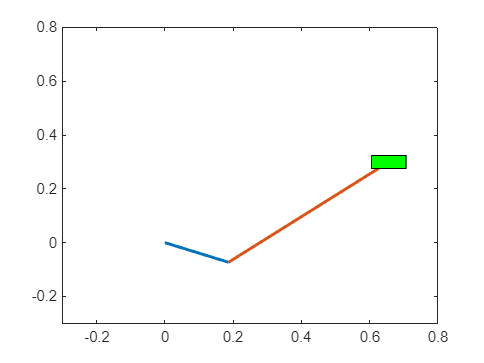

%Task X+1

%Now that you're done with analysis at a single point in time, analyze the
%system in a loop
clear 
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Initial Conditions and Lengths %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
L1 = .20; % [cm] Length of link AB
L2 = .60; % [cm] Length of link BC
Y = .30; % [cm] Horizontal offset of slider

m1 = 0.25; % mass of link AB
m2 = 0.75; % mass of link BC
mc = 0.5; % mass of the slider

IA = (1/3)*m1*L1^2; % moment of inertia of link AB about A
IG2 = (1/12)*m2*L2^2; % moment of inertia of link BC about its center of gravity G2
g = 9.81; % [m/s^2] gravitational constant
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dt = 0.001; % [s]
t = 0:dt:10; % [s]
theta1(1) = 0; % [rad]
w1(1) = 0; % [rad/s] 

for i=1:length(t)
    [theta2(i), w2(i), X(i), vc(i)] = ComputeKinematics(theta1(i), w1(i), L1, L2, Y);

    tau = 0;

b = [0;                                                              % Result 1
     m1*g;                                                           % Result 2
     -m1*g*(L1/2)*cos(theta1(i)) + tau;                              % Result 3
     -(w1(i)^2)*(L1/2)*cos(theta1(i));                               % Result 4
     -(w1(i)^2)*(L1/2)*sin(theta1(i));                               % Result 5
     0;                                                              % Result 6
     -m2*g;                                                          % Result 7
     0;                                                              % Result 8
     -(w1(i)^2)*L1*cos(theta1(i)) - (w2(i)^2)*(L2/2)*cos(theta2(i)); % Result 9
     -(w1(i)^2)*L1*sin(theta1(i)) - (w2(i)^2)*(L2/2)*sin(theta2(i)); % Result 10
     0;                                                              % Result 11
     mc*g;                                                           % Result 12
     -(w1(i)^2)*L1*cos(theta1(i)) - (w2(i)^2)*L2*cos(theta2(i));     % Result 13
     (w1(i)^2)*L1*sin(theta1(i)) + (w2(i)^2)*L2*sin(theta2(i))];     % Result 14

%                          1,                      2,   3,   4,  5,  6,  7, 8, 9,                    10,                     11,                    12,                     13,14
A = [                      0,                      0, -m1,   0,  0,  0,  0, 1, 0,                     1,                      0,                     0,                      0, 0;  % Equation 1
                           0,                      0,   0, -m1,  0,  0,  0, 0, 1,                     0,                      1,                     0,                      0, 0;  % Equation 2
                          IA,                      0,   0,   0,  0,  0,  0, 0, 0,     L1*sin(theta1(i)),     -L1*cos(theta1(i)),                     0,                      0, 0;  % Equation 3
       (L1/2)*sin(theta1(i)),                      0,   1,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 4
      -(L1/2)*cos(theta1(i)),                      0,   0,   1,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 5
                           0,                      0,   0,   0, m2,  0,  0, 0, 0,                     1,                      0,                    -1,                      0, 0;  % Equation 6
                           0,                      0,   0,   0,  0, m2,  0, 0, 0,                     0,                      1,                     0,                     -1, 0;  % Equation 7
                           0,                    IG2,   0,   0,  0,  0,  0, 0, 0, (L2/2)*sin(theta2(i)), -(L2/2)*cos(theta2(i)), (L2/2)*sin(theta2(i)), -(L2/2)*cos(theta2(i)), 0;  % Equation 8
           L1*sin(theta1(i)),  (L2/2)*sin(theta2(i)),   0,   0,  1,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 9
          -L1*cos(theta1(i)), -(L2/2)*cos(theta2(i)),   0,   0,  0,  1,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 10
                           0,                      0,   0,   0,  0,  0, mc, 0, 0,                     0,                      0,                     1,                      0, 0;  % Equation 11
                           0,                      0,   0,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                     -1, 1;  % Equation 12
           L1*sin(theta1(i)),      L2*sin(theta2(i)),   0,   0,  0,  0,  1, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 13
           L1*cos(theta1(i)),      L2*cos(theta2(i)),   0,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0]; % Equation 14

    Variables = A\b; %Solve the system of linear equations
    alpha1(i) = Variables(1);
    alpha2(i) = Variables(2);
    ac(i) = Variables(7);
    Ax(i) = Variables(8);
    Ay(i) = Variables(9);
    Bx(i) = Variables(10);
    By(i) = Variables(11);
    Cx(i) = Variables(12);
    Cy(i) = Variables(13);
    N(i) = Variables(14);

    w1(i+1) = w1(i) + alpha1(i)*dt; %apply numerical integration (Euler's Method)
    theta1(i+1) = theta1(i) + w1(i)*dt; %apply numerical integration (Euler's Method)
end
AnimateSlider(theta1,X) %to save you time, I created a code for you that does the slider animation automatically.

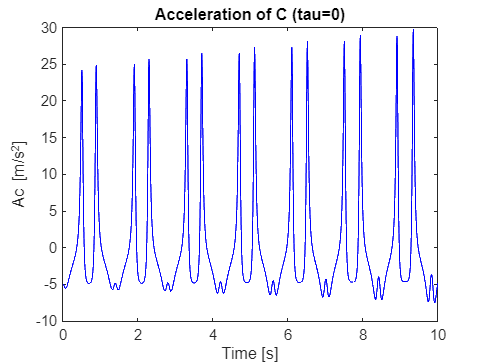

%all what you need to do is to feed it your theta1 array and X array
%(location of slider).
%PLOTS REQUESTED INSERT HERE
figure(1)
plot(t, ac, 'b', 'DisplayName', 'ac') % Adding labels for legend
title('Acceleration of C (tau=0)')
xlabel('Time [s]')
ylabel('Ac [m/s^2]')

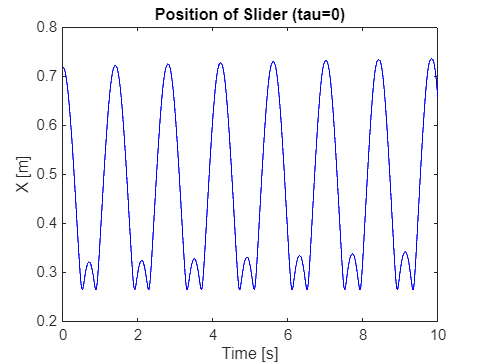


figure(3)
plot(t, X, 'b', 'DisplayName', 'X') % Adding labels for legend
title('Position of Slider (tau=0)')
xlabel('Time [s]')
ylabel('X [m]')

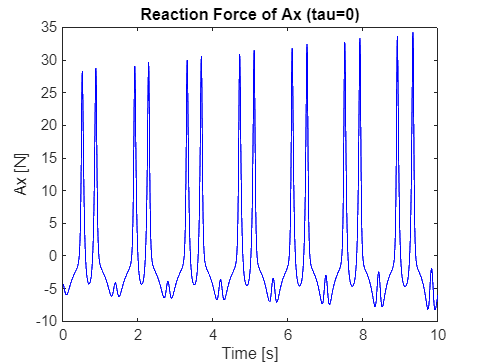


figure(4)
plot(t, Ax, 'b', 'DisplayName', 'Ax') % Adding labels for legend
title('Reaction Force of Ax (tau=0)')
xlabel('Time [s]')
ylabel('Ax [N]')

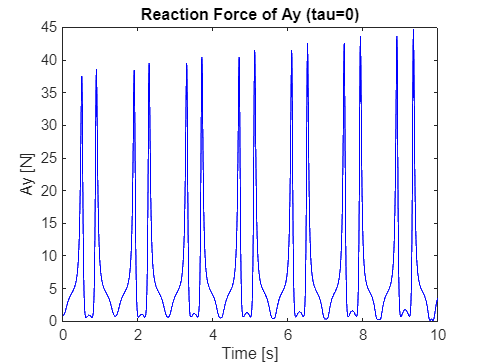


figure(5)
plot(t, Ay, 'b', 'DisplayName', 'Ay') % Adding labels for legend
title('Reaction Force of Ay (tau=0)')
xlabel('Time [s]')
ylabel('Ay [N]')

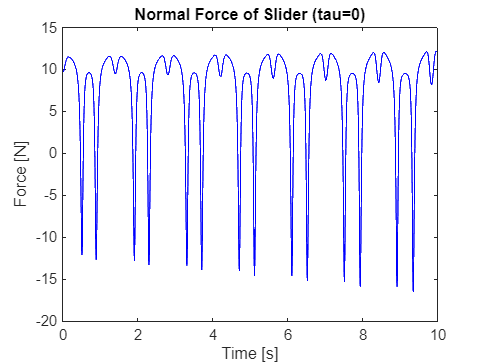


figure(6)
plot(t, N, 'b', 'DisplayName', 'N') % Adding labels for legend
title('Normal Force of Slider (tau=0)')
xlabel('Time [s]')
ylabel('Force [N]')

**tau = 0.3sin(0.1*pi*t)**

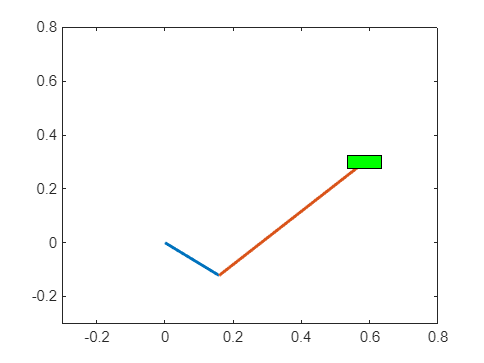

%Task X+1

%Now that you're done with analysis at a single point in time, analyze the
%system in a loop
clear 
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Initial Conditions and Lengths %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
L1 = .20; % [cm] Length of link AB
L2 = .60; % [cm] Length of link BC
Y = .30; % [cm] Horizontal offset of slider

m1 = 0.25; % mass of link AB
m2 = 0.75; % mass of link BC
mc = 0.5; % mass of the slider

IA = (1/3)*m1*L1^2; % moment of inertia of link AB about A
IG2 = (1/12)*m2*L2^2; % moment of inertia of link BC about its center of gravity G2
g = 9.81; % [m/s^2] gravitational constant
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dt = 0.001; % [s]
t = 0:dt:10; % [s]
theta1(1) = 0; % [rad]
w1(1) = 0; % [rad/s] 

for i=1:length(t)
    [theta2(i), w2(i), X(i), vc(i)] = ComputeKinematics(theta1(i), w1(i), L1, L2, Y);

    tau = 0.3*sin(0.1*pi*t(i));

b = [0;                                                              % Result 1
     m1*g;                                                           % Result 2
     -m1*g*(L1/2)*cos(theta1(i)) + tau;                              % Result 3
     -(w1(i)^2)*(L1/2)*cos(theta1(i));                               % Result 4
     -(w1(i)^2)*(L1/2)*sin(theta1(i));                               % Result 5
     0;                                                              % Result 6
     -m2*g;                                                          % Result 7
     0;                                                              % Result 8
     -(w1(i)^2)*L1*cos(theta1(i)) - (w2(i)^2)*(L2/2)*cos(theta2(i)); % Result 9
     -(w1(i)^2)*L1*sin(theta1(i)) - (w2(i)^2)*(L2/2)*sin(theta2(i)); % Result 10
     0;                                                              % Result 11
     mc*g;                                                           % Result 12
     -(w1(i)^2)*L1*cos(theta1(i)) - (w2(i)^2)*L2*cos(theta2(i));     % Result 13
     (w1(i)^2)*L1*sin(theta1(i)) + (w2(i)^2)*L2*sin(theta2(i))];     % Result 14

%                          1,                      2,   3,   4,  5,  6,  7, 8, 9,                    10,                     11,                    12,                     13,14
A = [                      0,                      0, -m1,   0,  0,  0,  0, 1, 0,                     1,                      0,                     0,                      0, 0;  % Equation 1
                           0,                      0,   0, -m1,  0,  0,  0, 0, 1,                     0,                      1,                     0,                      0, 0;  % Equation 2
                          IA,                      0,   0,   0,  0,  0,  0, 0, 0,     L1*sin(theta1(i)),     -L1*cos(theta1(i)),                     0,                      0, 0;  % Equation 3
       (L1/2)*sin(theta1(i)),                      0,   1,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 4
      -(L1/2)*cos(theta1(i)),                      0,   0,   1,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 5
                           0,                      0,   0,   0, m2,  0,  0, 0, 0,                     1,                      0,                    -1,                      0, 0;  % Equation 6
                           0,                      0,   0,   0,  0, m2,  0, 0, 0,                     0,                      1,                     0,                     -1, 0;  % Equation 7
                           0,                    IG2,   0,   0,  0,  0,  0, 0, 0, (L2/2)*sin(theta2(i)), -(L2/2)*cos(theta2(i)), (L2/2)*sin(theta2(i)), -(L2/2)*cos(theta2(i)), 0;  % Equation 8
           L1*sin(theta1(i)),  (L2/2)*sin(theta2(i)),   0,   0,  1,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 9
          -L1*cos(theta1(i)), -(L2/2)*cos(theta2(i)),   0,   0,  0,  1,  0, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 10
                           0,                      0,   0,   0,  0,  0, mc, 0, 0,                     0,                      0,                     1,                      0, 0;  % Equation 11
                           0,                      0,   0,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                     -1, 1;  % Equation 12
           L1*sin(theta1(i)),      L2*sin(theta2(i)),   0,   0,  0,  0,  1, 0, 0,                     0,                      0,                     0,                      0, 0;  % Equation 13
           L1*cos(theta1(i)),      L2*cos(theta2(i)),   0,   0,  0,  0,  0, 0, 0,                     0,                      0,                     0,                      0, 0]; % Equation 14

    Variables = A\b; %Solve the system of linear equations
    alpha1(i) = Variables(1);
    alpha2(i) = Variables(2);
    ac(i) = Variables(7);
    Ax(i) = Variables(8);
    Ay(i) = Variables(9);
    Bx(i) = Variables(10);
    By(i) = Variables(11);
    Cx(i) = Variables(12);
    Cy(i) = Variables(13);
    N(i) = Variables(14);

    w1(i+1) = w1(i) + alpha1(i)*dt; %apply numerical integration (Euler's Method)
    theta1(i+1) = theta1(i) + w1(i)*dt; %apply numerical integration (Euler's Method)
end

AnimateSlider2(theta1,X) %to save you time, I created a code for you that does the slider animation automatically.

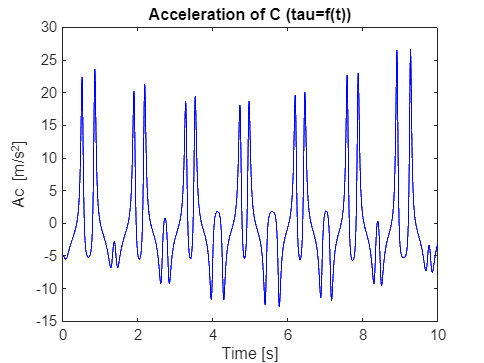

%all what you need to do is to feed it your theta1 array and X array
%(location of slider).
%PLOTS REQUESTED INSERT HERE
figure(7)
plot(t, ac, 'b', 'DisplayName', 'ac') % Adding labels for legend
title('Acceleration of C (tau=f(t))')
xlabel('Time [s]')
ylabel('Ac [m/s^2]')

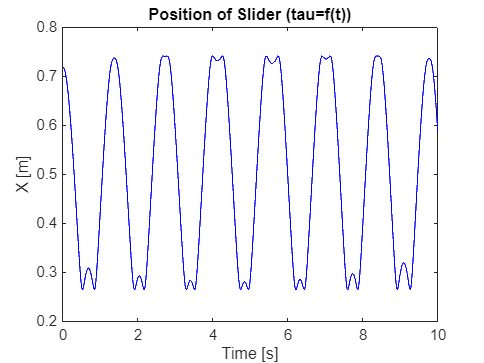


figure(9)
plot(t, X, 'b', 'DisplayName', 'X') % Adding labels for legend
title('Position of Slider (tau=f(t))')
xlabel('Time [s]')
ylabel('X [m]')

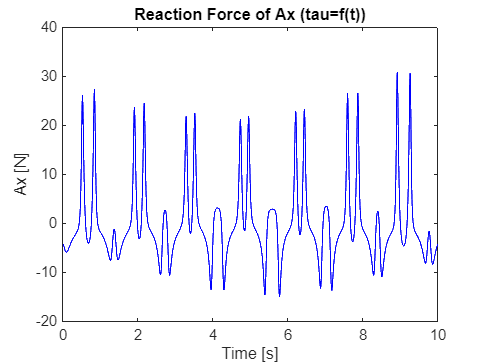


figure(10)
plot(t, Ax, 'b', 'DisplayName', 'Ax') % Adding labels for legend
title('Reaction Force of Ax (tau=f(t))')
xlabel('Time [s]')
ylabel('Ax [N]')

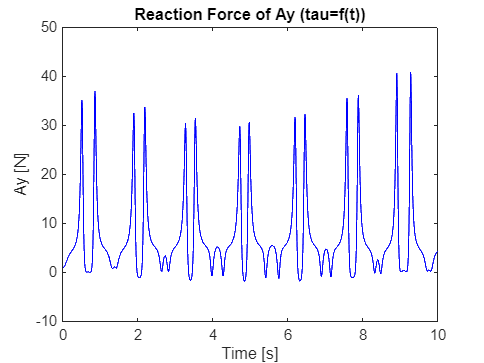


figure(11)
plot(t, Ay, 'b', 'DisplayName', 'Ay') % Adding labels for legend
title('Reaction Force of Ay (tau=f(t))')
xlabel('Time [s]')
ylabel('Ay [N]')

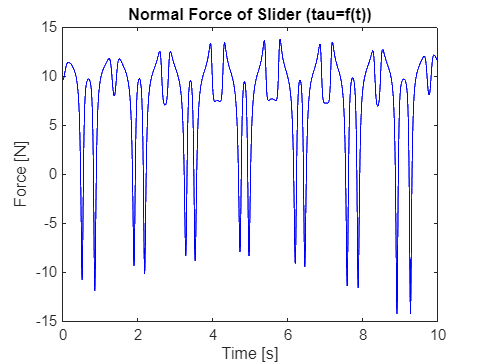


figure(12)
plot(t, N, 'b', 'DisplayName', 'N') % Adding labels for legend
title('Normal Force of Slider (tau=f(t))')
xlabel('Time [s]')
ylabel('Force [N]')

%Once things are found, this function can be used to compute the rest of
%the kinematics
function [theta2, w2, X, vc] = ComputeKinematics(theta1, w1, L1, L2, Y) 
    X = L1*cos(theta1)+sqrt(L2^2-(Y-L1*sin(theta1))^2);
    theta2 = atan2(Y-L1*sin(theta1),X-L1*cos(theta1));
    w2 = -L1*cos(theta1)*w1/(L2*cos(theta2));
    vc = -(L1*w1*sin(theta1)+L2*w2*sin(theta2));
end

%A function that animates your slider motion when given the theta1 array
%and X array. Nothing needs to be modified here

function [] = AnimateSlider(theta1,X)
    for i=1:10:length(theta1)
        i;
        L1 = .20;
        L2 = .60;
        Y = .30;
        X1 = L1*cos(theta1(i));
        Y1 = L1*sin(theta1(i));
        figure(2)
        plot([0,X1],[0,Y1],'LineWidth',2)
        hold on
        plot([X1,X(i)],[Y1,Y],'LineWidth',2)
        [X_box, Y_box] = RectangularEdges(X(i), Y, .10, .05);
        fill(X_box, Y_box, 'g');
        hold off
        xlim([-.30,.80])
        ylim([-.30,.80])
        pause(0.01)
    end
end

function [] = AnimateSlider2(theta1,X)
    for i=1:10:length(theta1)
        i;
        L1 = .20;
        L2 = .60;
        Y = .30;
        X1 = L1*cos(theta1(i));
        Y1 = L1*sin(theta1(i));
        figure(8)
        plot([0,X1],[0,Y1],'LineWidth',2)
        hold on
        plot([X1,X(i)],[Y1,Y],'LineWidth',2)
        [X_box, Y_box] = RectangularEdges(X(i), Y, .10, .05);
        fill(X_box, Y_box, 'g');
        hold off
        xlim([-.30,.80])
        ylim([-.30,.80])
        pause(0.01)
    end
end

%A function that defines the boundaries of a rectangular box given the
%location of its center and its width and height.
function [X,Y] = RectangularEdges(CenterX, CenterY, W, H)
    X = [CenterX-W/2, CenterX+W/2, CenterX+W/2, CenterX-W/2];
    Y = [CenterY+H/2, CenterY+H/2, CenterY-H/2, CenterY-H/2];
end